# **Signals and Systems**

## **Experiment No. # 10**

 **Objective:**

The objective of this lab is to create a practical understanding of the Discrete Time Fourier Series (Chapter 3 of textbook) and to prove some properties of the DTFS.

**Theoretical Background:**

The Discrete Time Fourier Series is used for representation of discrete-time periodic signals:

DTFS representation of a periodic signal:                        

Fourier Series Coefficients of a periodic signal:

**Periodic Convolution:**

The convolution of two periodic sequences is calculated through periodic convolution. The basic idea is to take one period of each signal and perform periodic convolution to get one period of the resultant sequence. Then this one period is repeated over all time to create a periodic sequence. The formula for periodic convolution is:

- where x1[n] and x2[n] are two discrete time periodic sequences and y[n] is one period of a discrete time periodic sequence

- N is the length of each sequence

**Properties of the Discrete Time Fourier Series:**

There are many properties associated with the DTFS, in this lab the students will prove the following two properties, where:

- x(t) and y(t) are two continuous time periodic signals with period T and fundamental frequency and are the Fourier Series Coefficients

- Periodic Convolution:

- This property states that the DTFS of periodic convolution of two discrete time periodic sequences is equal to multiplication of the DFS coefficients of the sequences.

- Frequency Shifting:

- The shifting of DFS coefficients is equivalent to multiplication of complex exponential to the actual periodic signal. 

**Tasks:**

The following tasks are to be performed by each student:

**Task 1:**

Create separate functions in MATLAB for Discrete Time Fourier Series (DTFS), i.e. Fourier series coefficients of a signal and the Inverse Discrete Time Fourier Series (IDTFS), i.e. creating signal from Fourier Series Coefficients.

**Task 2:**

a). Create a function that performs periodic convolution on two discrete time periodic sequences of same length.

b). Using the functions for DTFS and IDTFS created in Task 1 and the function for periodic convolution, prove the following properties (explained in theoretical background) of DTFS:

- Periodic Convolution

- Frequency Shifting

The specifications of the two signals are:

- x[n]=[1 2 1 2 1 2 1]

- y[n]=[1 0 1 0 1 0 1]

- The period N is the length of the signal

**Task 3:**

Take the discrete time periodic square wave as shown below:

Take N1=5 and the number of zeros in each period is also equal to N1 (Example 3.12 of textbook)

Calculate the DTFS of this square wave, then calculate its inverse DTFS using the IDTFS function. Plot the original signal, the DTFS and the IDTFS results in the same figure using subplot.

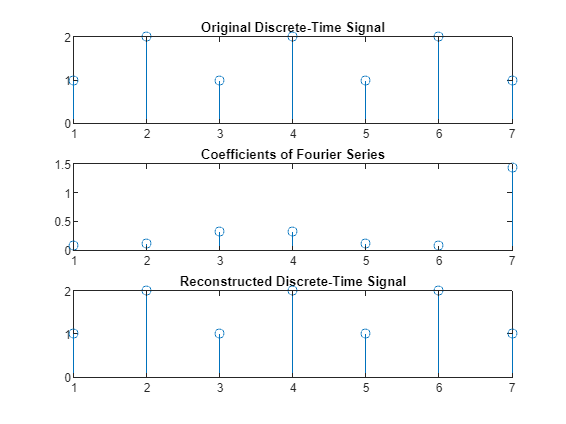

x = [1 2 1 2 1 2 1];
N = length(x);
ak = DTFS(x, N);
x1 = IDTFS(ak, N);
subplot(3,1,1);
stem(abs(x));
title('Original Discrete-Time Signal');
subplot(3,1,2);
stem(abs(ak));
title('Coefficients of Fourier Series');
subplot(3,1,3);
stem(abs(x1));
title('Reconstructed Discrete-Time Signal');

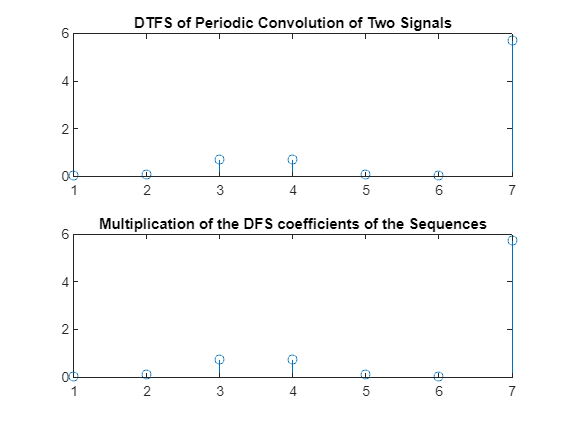

x=[1 2 1 2 1 2 1];
y=[1 0 1 0 1 0 1];

z = periodic_convolution(x,y);
LHS = DTFS(z,N);

figure;
subplot(2,1,1);
stem(abs(LHS));
title('DTFS of Periodic Convolution of Two Signals');

ak = DTFS(x,N);
bk = DTFS(y,N);
N = length(x);

RHS = N.*ak.*bk;
subplot(2,1,2);
stem(abs(RHS));
title('Multiplication of the DFS coefficients of the Sequences');

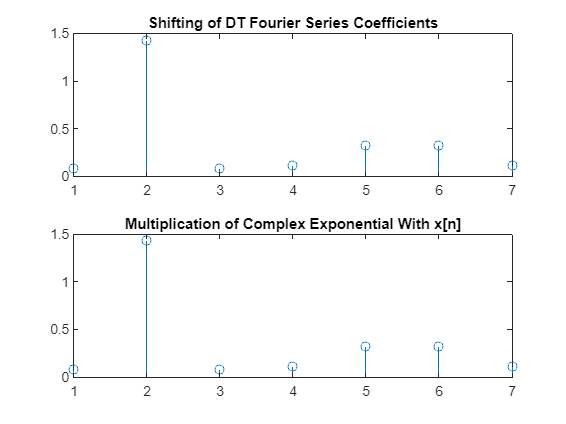

a = zeros(1:N);
%M = input("Enter value of shift: ");
M = 9;
% LHS
for n = 1:N
 a(n) = exp(1i * 2 * pi * M * (n/ N)) * x (n);
end

LHS = DTFS(a,N);

figure;
subplot(2,1,1);
stem(abs(LHS));
title('Shifting of DT Fourier Series Coefficients');

% RHS
z = DTFS(x,N);
RHS = circshift(z, [0 M]);

subplot(2,1,2);
stem(abs(RHS));
title('Multiplication of Complex Exponential With x[n]')

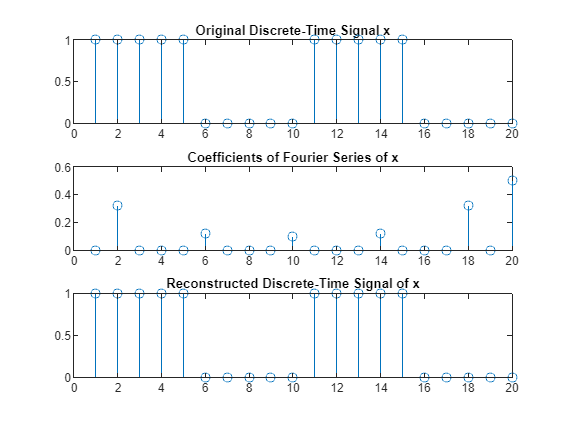

A = [ones(1,5) zeros(1,5)];
x = [A A];
N = length(x);

x_DTFS =  DTFS(x,N);
x_IDTFS = IDTFS(x_DTFS,N);

figure;
subplot(3,1,1);
stem(abs(x));
title('Original Discrete-Time Signal x');
subplot(3,1,2);
stem(abs(x_DTFS));
title('Coefficients of Fourier Series of x');
subplot(3,1,3);
stem(abs(x_IDTFS));
title('Reconstructed Discrete-Time Signal of x');